# Data Structures in MATLAB

In the world of "big data", processing large amounts of data efficiently and accurately is vital. MATLAB stores (and processes) data in a variety of ways. We have looked at numeric, char, string, and cell arrays for example, but MATLAB has numerous methods of storing a variety of different data types together. Let's look at two of them.

## Tables

In MATLAB, a table is an array with named columns which can contain different data types. The function `readtable` reads data from a file and puts it in names columns. The default names are quite uninformative: `Var1`, `Var2`, `Var3`, ... , but you can change those manually or with the first row of the table. 

You can create a table from arrays of the same size with 

but it is easier to import data from a file. Let's look at the file `sunspotsbyyear.csv` in the data folder on github,

[path,fold] = fileparts(pwd)

path = 'C:\Users\Tom K\Google Drive\Programs\courses\CompProbSol'

fold = 'problem4'

full = fullfile(path,'data','sunspotsbyyear.csv')

full = 'C:\Users\Tom K\Google Drive\Programs\courses\CompProbSol\data\sunspotsbyyear.csv'

sunspots = readtable(full)

sunspots = 316×5 table
     Var1     Var2    Var3    Var4    Var5
    ______    ____    ____    ____    ____

    1700.5     8.3     -1      -1      1  
    1701.5    18.3     -1      -1      1  
    1702.5    26.7     -1      -1      1  
    1703.5    38.3     -1      -1      1  
    1704.5      60     -1      -1      1  
    1705.5    96.7     -1      -1      1  
    1706.5    48.3     -1      -1      1  
    1707.5    33.3     -1      -1      1  
    1708.5    16.7     -1      -1      1  
    1709.5    13.3     -1      -1      1  
    1710.5       5     -1      -1      1  
    1711.5       0     -1      -1      1  
    1712.5       0     -1      -1      1  
    1713.5     3.3     -1      -1      1  
    1714.5    18.3     -1      -1      1  
    1715.5      45     -1      -1      1  


sunspots.Properties.VariableNames = {'year' 'nspots' 'std' 'nobs' 'integ'}

sunspots = 316×5 table
     year     nspots    std    nobs    integ
    ______    ______    ___    ____    _____

    1700.5      8.3     -1      -1       1  
    1701.5     18.3     -1      -1       1  
    1702.5     26.7     -1      -1       1  
    1703.5     38.3     -1      -1       1  
    1704.5       60     -1      -1       1  
    1705.5     96.7     -1      -1       1  
    1706.5     48.3     -1      -1       1  
    1707.5     33.3     -1      -1       1  
    1708.5     16.7     -1      -1       1  
    1709.5     13.3     -1      -1       1  
    1710.5        5     -1      -1       1  
    1711.5        0     -1      -1       1  
    1712.5        0     -1      -1       1  
    1713.5      3.3     -1      -1       1  
    1714.5     18.3     -1      -1       1  
    1715.5       45     -1      -1       

You access the elements of the table using *dot notation *and the traditional indexing in MATLAB

sunspots.nspots(100:105)

ans =    11.3000
   24.2000
   56.7000
   75.0000
   71.8000
   79.2000


sunspots.nspots(sunspots.year>2000)

ans =   173.9000
  170.4000
  163.6000
   99.3000
   65.3000
   45.8000
   24.7000
   12.6000
    4.2000
    4.8000


sum(sunspots.nobs)

ans = 282010

You can even get summary statistics on each of the variables,

summary(sunspots)


Variables:

    year: 316×1 double

        Values:

            Min       1700.5
            Median      1858
            Max       2015.5

    nspots: 316×1 double

        Values:

            Min            0  
            Median      66.7  
            Max        269.3  

    std: 316×1 double

        Values:

            Min         -1 
            Median     4.2 
            Max       19.1 

    nobs: 316×1 double

        Values:

            Min          -1 
            Median      365 
            Max        8903 

    integ: 316×1 double

        Values:

            Min          1   
            Median       1   
            Max          1   



and plot them just like any other numbers

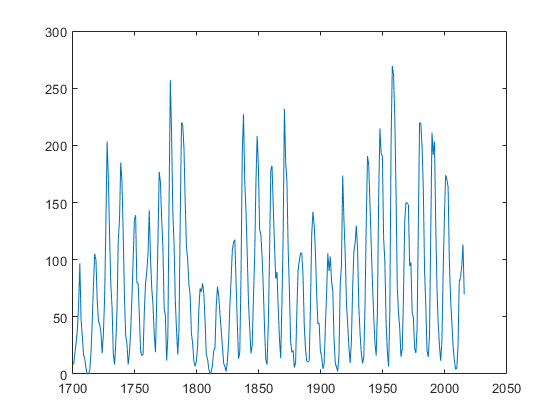

plot(sunspots.year,sunspots.nspots)

## Structures

A structure array is a data type that groups related data using data containers called *fields*. Each field can contain any data type. Structures use the same dot notation that tables do: `structName.fieldName.`

You can create a structure "by hand" with the function `struct`. 

S = struct('Name','Jean-Luc Picard','Rank','Captain','Age',55,'FantScore',300)

S = struct with fields:
         Name: 'Jean-Luc Picard'
         Rank: 'Captain'
          Age: 55
    FantScore: 300


S.Age

ans = 55

S(2) = struct('Name','William Riker','Rank','Commander','Age',38,'FantScore',340);
fieldnames(S)

ans = 4×1 cell array
    {'Name'     }
    {'Rank'     }
    {'Age'      }
    {'FantScore'}


S(2).FavGame = "Poker" 

S = 1×2 struct array with fields:
    Name
    Rank
    Age
    FantScore
    FavGame


S(1).FavGame


ans =

     []



But like most things it's easier to import data or *convert* from an already existing data holder

spots=table2struct(sunspots)

spots = 316×1 struct array with fields:
    year
    nspots
    std
    nobs
    integ


The table from the previous section is now a `struct.` Specifically, it is now a struct array, each element in this array can be thought of as a "record". We can index the struct array like any other array.

spots(2)

ans = struct with fields:
      year: 1.7015e+03
    nspots: 18.3000
       std: -1
      nobs: -1
     integ: 1


We can use dot notation with any of the elements like any other struct:

spots(200).nspots

ans = 20.2000

We can get a list of field names:

f = fieldnames(spots)

f = 5×1 cell array
    {'year'  }
    {'nspots'}
    {'std'   }
    {'nobs'  }
    {'integ' }


We can check if a struct has a certain field:

isfield(spots,f{3})

ans = logical
   1


isfield(spots,'nspots')

ans = logical
   1


isfield(spots,'donuts')

ans = logical
   0


Can treat the data in the struct like other arrays as well?:

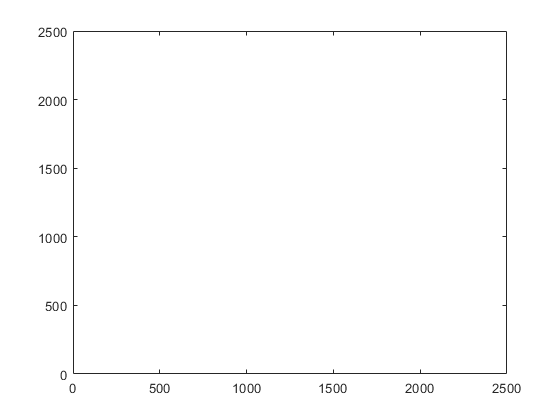

plot(spots.year,spots.nspots)

## Interesting use case for a Structure

You can store any type of data in a structure. Below is some code that shows how you can store similar data that naturally doesn't belong in a tabular format.

Im = load('flujet.mat') 

Im = struct with fields:
          X: [400×300 double]
        map: [64×3 double]
    caption: [2×32 char]


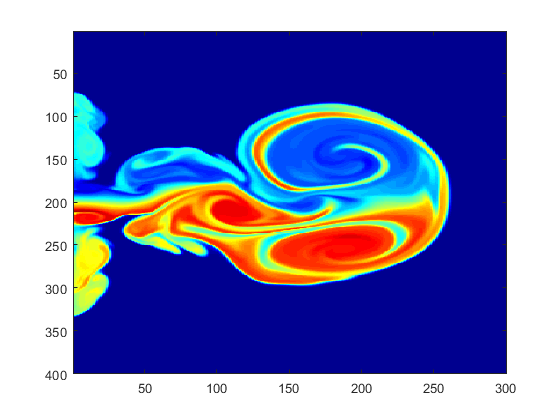

image(Im.X) 
colormap(Im.map)

Add to the structure called `Im`

Im(2) = load('cape.mat') 

Im = 1×2 struct array with fields:
    X
    map
    caption


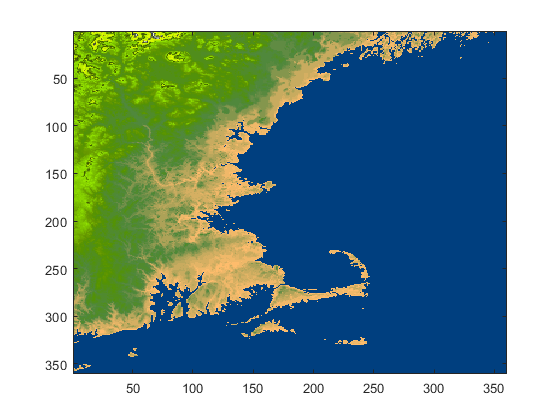

image(Im(2).X) 
colormap(Im(2).map)

Im(1).caption

ans = 2×32 char array
    'Astrophysical jet from NCSA.    '
    'One fluid collides with another.'


Im(2).caption

ans = 2×55 char array
    'NOAA altitude data for New England, including Cape Cod.'
    'Pseudocolor map uses blue for zero altitude.           '


%char2string(Im(2).caption)

Unrecognized function or variable 'char2string'.

**Side Note: **This is the draw back of saving statements in a character array. Look at all the wasted space in the output above.